# Simulate the central limit theorem with bimodal data

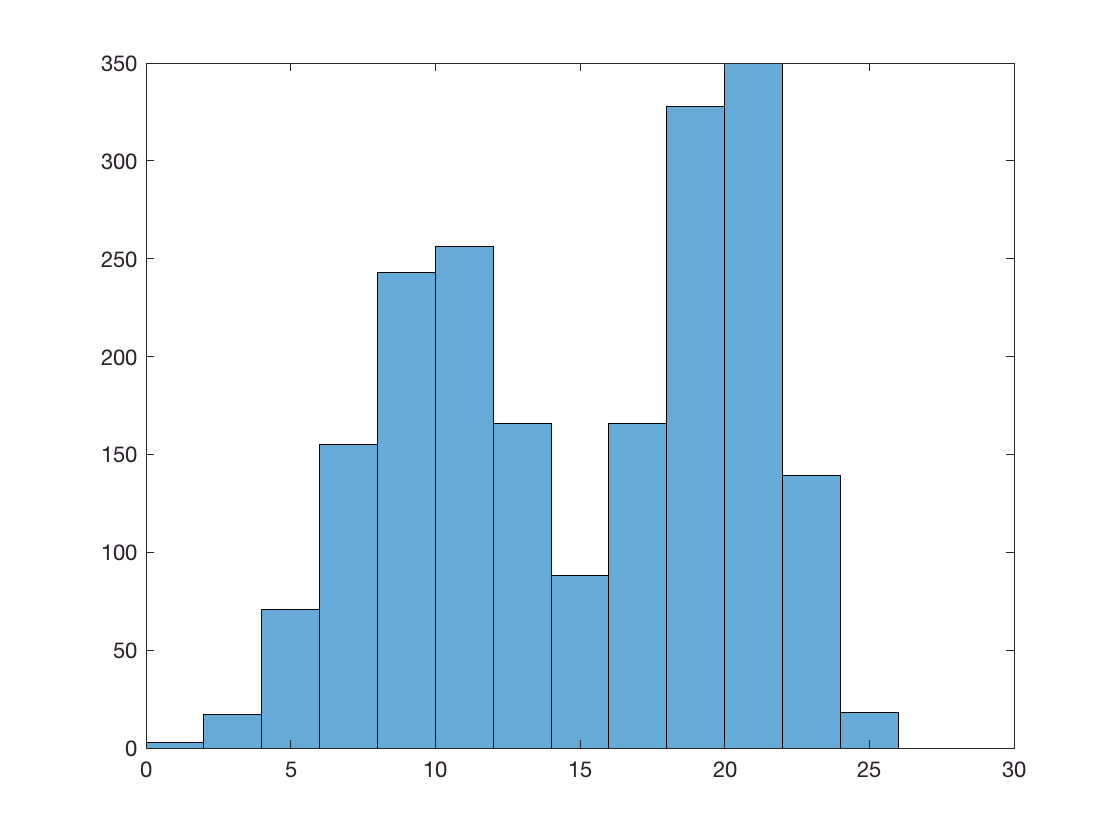

% data generation
a = [normrnd(10,3,1000,1);normrnd(20,2,1000,1)];
histogram(a);

## random sampling


% random sampling n = 10, 30, 60, 100

sample_n = [10 30 60 100];
for iter = 1:10000
    for i = 1:numel(sample_n)
        m{i}(iter,1) = mean(a(randperm(numel(a),i)));
    end
end


## figure

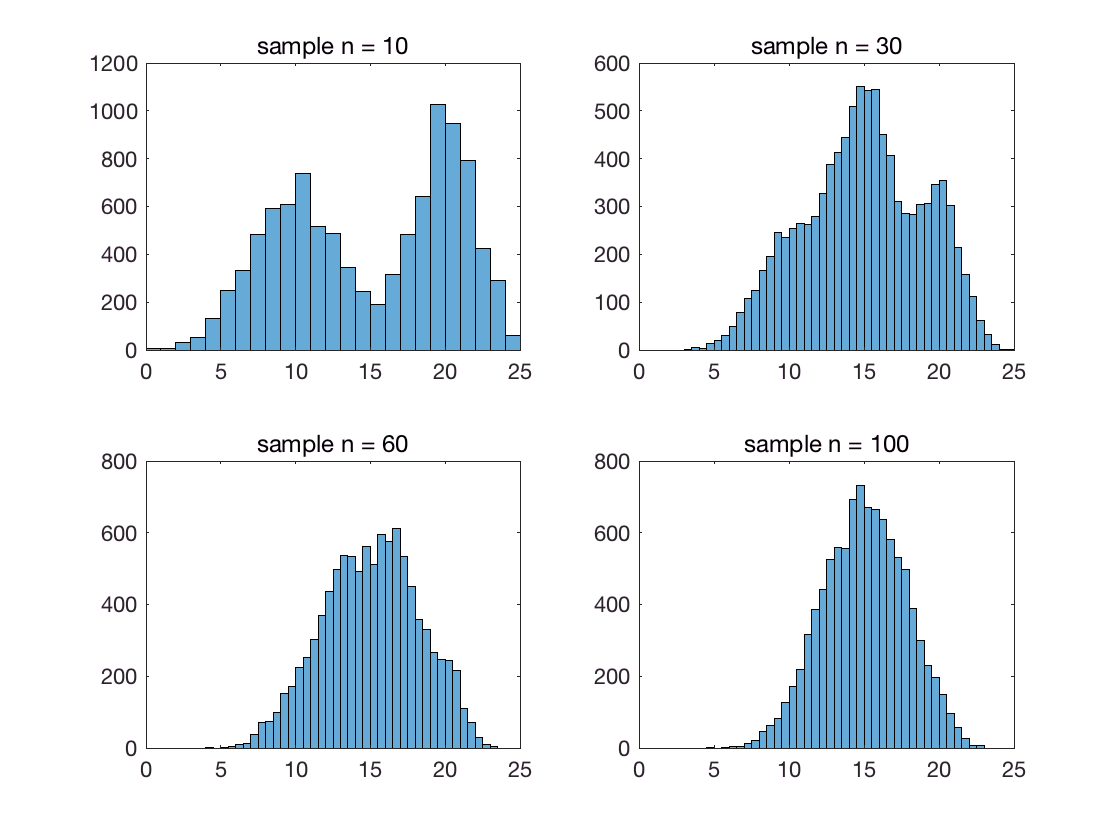

for i = 1:numel(m)
    subplot(2,2,i);
    histogram(m{i});
    set(gca, 'xlim', [0 25]);
    title(['sample n = ' num2str(sample_n(i))]);
end